# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：    王晨晖      学号：   24307163       专业：   电子信息工程   

## 实验七 FIR数字滤波器

## 一、实验目的

- 掌握线性相位滤波器符幅特性和零极点分布的研究方法

- 用MATLAB研究线性相位滤波器特性时程序编写思路和方法

- 加深对窗函数法设计FIR数字滤波器的基本原理的理解

- 用MATLAB的窗函数法编写设计FIR数字滤波器的程序

- 加深对频率采样法设计FIR数字滤波器的基本原理的理解

- 掌握在频域优化设计FIR数字滤波器的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

1、FIR 滤波器的基本特性

与 IIR 滤波器相比，FIR 滤波器在保证任意幅频特性的同时，可以兼具严格的线性相位特性。其单位冲激响应 h(n)*h*(*n*) 为有限长序列（长度为 N*N*），系统函数为：

H(z)=∑n=0N−1h(n)z−n*H*(*z*)=∑*n*=0*N*−1�*h*(*n*)*z*−*n*

2、线性相位条件与四种类型

当滤波器系数满足特定对称条件时，可实现线性相位。根据系数的对称性与 N*N* 的奇偶性，线性相位 FIR 滤波器分为四种类型：

- I 型：系数偶对称（h(n)=h(N−1−n)*h*(*n*)=*h*(*N*−1−*n*)），N*N* 为奇数；

- II 型：系数偶对称（h(n)=h(N−1−n)*h*(*n*)=*h*(*N*−1−*n*)），N*N* 为偶数；

- III 型：系数奇对称（h(n)=−h(N−1−n)*h*(*n*)=−*h*(*N*−1−*n*)），N*N* 为奇数；

- IV 型：系数奇对称（h(n)=−h(N−1−n)*h*(*n*)=−*h*(*N*−1−*n*)），N*N* 为偶数。

各类型的幅频特性 A(ω)*A*(*ω*) 可表示为关于 ω*ω* 的余弦（偶对称）或正弦（奇对称）的加权和，群延迟为常数 τ=(N−1)/2*τ*=(*N*−1)/2。

3、窗函数法设计 FIR 滤波器

窗函数法的核心思想是：首先确定理想滤波器的频率响应 Hd(ejω)*H**d*�(*e**jω*)，对其进行反变换得到无限长冲激响应 hd(n)*h**d*�(*n*)，再乘以长度为 N*N* 的窗函数 w(n)*w*(*n*)，截断为有限长序列：

h(n)=hd(n)⋅w(n),0≤n≤N−1*h*(*n*)=*h**d*�(*n*)⋅*w*(*n*),0≤*n*≤*N*−1

理想低通滤波器的冲激响应为：hd(n)=sin [ωc(n−τ)]π(n−τ)*h**d*�(*n*)=*π*(*n*−*τ*)sin[*ω**c*�(*n*−*τ*)]�

其中 ωc*ω**c*� 为截止频率，τ=(N−1)/2*τ*=(*N*−1)/2 为群延迟。常用窗函数包括矩形窗（Boxcar）、三角窗（Bartlett）、Hamming 窗、Hanning 窗、Blackman 窗及 Chebyshev 窗（chebwin）和 Kaiser 窗，各窗函数在过渡带宽度与阻带衰减之间存在不同的折中关系，应根据技术指标选用。

4、频率采样法设计 FIR 滤波器

频率采样法的基本思路是：在 [0,2π)[0,2*π*) 上均匀取 N 个频率采样点，指定各点处的期望频率响应值 H(k)*H*(*k*)，然后通过离散傅里叶逆变换（IDFT）求得滤波器系数：

h(n)=1N∑k=0N−1H(k)ej2πkn/N,0≤n≤N−1*h*(*n*)=*N*1�∑*k*=0*N*−1�*H*(*k*)*e**j*2*πkn*/*N*,0≤*n*≤*N*−1

实际的 FIR 滤波器系数由系统函数 H(z)*H*(*z*) 确定，频率采样点数 N*N* 与滤波器长度 M*M* 之间通常取 N=M*N*=*M*。为保证系数为实数，频率采样点的幅频响应应关于 ω=π*ω*=*π* 共轭对称；为满足线性相位条件，频率采样点应选取为奇数个，且相位响应应为实奇函数。设计时，在通带与阻带之间添加过渡采样点（即让边界处的频率响应取 00 与 11 之间的中间值）可有效降低过渡带的纹波，改善滤波器性能。

## 四、实验所用MATLAB函数

- `fir1(n, Wn)` / `fir1(n, Wn, ftype, Window)`：基于标准频率响应，利用窗函数法设计 FIR 滤波器。`n` 为滤波器阶数，`Wn` 为归一化截止频率（0∼10∼1，对应 0∼π0∼*π*），`ftype` 可指定滤波器类型（如 `'high'`、`'bandpass'`、`'stop'`），`Window` 指定所用窗函数向量。

- `fir2(n, f, m)`：基于任意分段线性频率响应的加窗法设计 FIR 滤波器。`n` 为滤波器阶数，`f` 为频率向量（0∼10∼1），`m` 为对应各频率点的期望幅度值。该函数适用于设计具有任意频率响应的 FIR 滤波器。

- `freqz(b, a, N, 'whole')`：计算数字滤波器的频率响应，`b`、`a` 分别为分子、分母多项式系数，`N` 为计算点数，`'whole'` 表示计算 [0,2π)[0,2*π*) 的完整频率范围，返回复数频率响应 H*H* 及对应角频率向量 ω*ω*。

- `freqz_m(b, a)`（自定义函数）：对 `freqz` 的封装，计算并返回滤波器的幅频响应（dB 值 `db`、线性幅度 `mag`）、相频响应 `pha` 及群延迟 `grd`，便于一次调用获取全部频率域特性。

- `grpdelay(b, a, w)`：计算数字滤波器在指定频率处的群延迟，即相位响应对频率的负导数 τ(ω)=−dϕ(ω)dω*τ*(*ω*)=−*d**ω**d**ϕ*(*ω*)�，用于验证线性相位特性是否成立。

            实验专用自定义函数

- `ideal_lp(wc, N)`：计算理想低通滤波器在 [0,N−1][0,*N*−1] 范围内的单位冲激响应，输入参数为截止频率 `wc`（弧度）和长度 `N`，返回截断的理想低通冲激响应向量 `hd`。多个理想低通响应相减即可构造带通或高通理想滤波器响应。

- `amplres(h)`：计算 FIR 滤波器系数 `h` 对应的幅频特性 A(ω)*A*(*ω*)，并自动判断滤波器属于四种线性相位类型中的哪一种（返回 `type`），同时给出群延迟 `tao`。函数通过判断系数的偶对称或奇对称性，分别用余弦或正弦加权求和公式计算实幅频响应，是分析线性相位特性的核心工具。

## 五、实验内容、方法、代码与结果

### **题目1**：有以下四种类型的线性相位FIR滤波器，即

#### $h1=[3,-1,2,-3,5,-3,2,-1,3]$;

#### $h2=[1,1,2,3,3,2,1,1]$;

#### $h3=[3,-1,2,-3,0,3,-2,1,-3]$;

#### $h4=[3,-1,2,-3,3,-2,1,-3]$;

### 分别求它们幅度特性$H_g(w)$,（利用教材表7.1.1的公式，也可以调用下述函数），并在同一张图纸上描绘出来进行分析比较，观察并指出关于0，$\pi$和$2\pi$的对称性。

**解答1**：

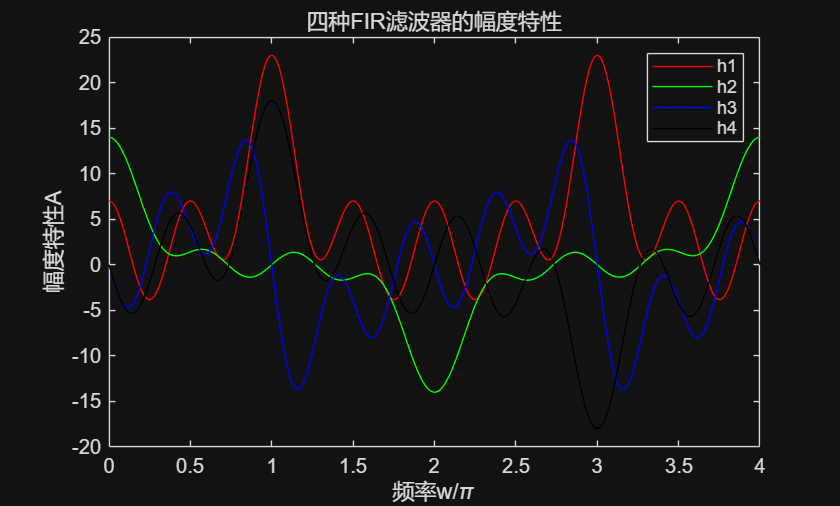

% Insert your code here
h1 = [3 -1 2 -3 5 -3 2 -1 3];
h2 = [1 1 2 3 3 2 1 1];
h3 = [3 -1 2 -3 0 3 -2 1 -3];
h4 = [3 -1 2 -3 3 -2 1 -3];

[A1,w1,type1,tao1] = amplres(h1);
[A2,w2,type2,tao2] = amplres(h2); 
[A3,w3,type3,tao3] = amplres(h3);
[A4,w4,type4,tao4] = amplres(h4);

figure;
plot(w1/pi,A1,"Color",'r');
hold on;
plot(w2/pi,A2,"Color",'g');
plot(w3/pi,A3,"Color",'b');
plot(w4/pi,A4,"Color",'k');

ylabel('幅度特性A');
xlabel('频率w/\pi');
legend('h1','h2','h3','h4');
title('四种FIR滤波器的幅度特性');

%指出关于0，pi，2pi处的对称性
disp('h1的幅度特性在0,pi,2pi处偶对称');

h1的幅度特性在0,pi,2pi处偶对称


disp('h2的幅度特性在0,2pi处偶对称,在pi处奇对称');

h2的幅度特性在0,2pi处偶对称,在pi处奇对称


disp('h3的幅度特性在0,pi,2pi处奇对称');

h3的幅度特性在0,pi,2pi处奇对称


disp('h4的幅度特性在0,2pi处奇对称,在pi处偶对称');

h4的幅度特性在0,2pi处奇对称,在pi处偶对称


function[A,w,type,tao] = amplres(h)
% 给定FIR滤波器系数,求滤波器符幅特性
% h＝FIR滤波器的脉冲响应或分子系数向量
% A＝滤波器的幅度特性
% w＝频率向量,在0到pi之间分成500份,501个点

% type＝线性相位滤波器的类型
% tao＝符幅特性的群时延
N = length(h);tao = (N-1)/2;
L = floor((N-1)/2); % 求滤波器的阶次及符幅特性的阶次
n = 1:L+1;
w = [0:500]*4*pi/500; % 取滤波器频率向量
if all(abs(h(n)-h(N-n+1))<1e-10)   % 判断滤波器系数,若为对称
A = 2*h(n)*cos((n-1-tao)'*w)-mod(N,2)*h(L+1);
% 对称条件下计算A(两种类型)
% 在N＝奇数时,h(L+1)多算一倍,要减掉。N为偶数时,
% 乘以mod(N,2)以取消这项
type = 2-mod(N,2);     % 判断并给出类型
elseif all(abs(h(n)+h(N-n+1))<1e-10)&(h(L+1)*mod(N,2)==0) % 系数若为反对称
% 在N＝奇数时,h(L+1)为零是奇对称判别条件之一,
% N为偶数时,乘以mod(N,2)以取消这项
A = 2*h(n)*sin((n-1-tao)'*w); % 反对称条件下计算A(两种类型)
type = 4-mod(N,2); % 判断并给出类型
else error('错误：这不是线性相位滤波器!') % 滤波器系数非对称,报告错误
end
end

### **题目2**：求解线性相位系统$h=[3,-1,2,-3,6,-3,2,-1,3]$的零极点分布图，并观察实数零点和复数零点成组出现的特点。

**解答2**：

% Insert your code here
h = [3 -1 2 -3 6 -3 2 -1 3];
%求零极点分布图

figure;
zplane(h,1);
title('FIR滤波器的零极点分布图');

实数零点单独出现，而复数零点共轭对称出现

### **题目3**：选择合适的窗函数设计FIR数字低通滤波器，要求通带$\omega_{p}=0.2\pi,R_{p}=0.5dB$；阻带$\omega_s=0.3\pi,A_s=40dB$。描绘实际滤波器的脉冲响应、窗函数及滤波器的幅频响应曲线（dB显示）和相频响应曲线。

**解答3**：

% Insert your code here
wp = 0.2*pi;
ws = 0.3*pi;
Rp = 0.5;
As = 40;
%窗函数法设计FIR滤波器
N = 8*pi/(ws-wp);
N = ceil(N);
n = 0:N-1;

wc = (wp+ws)/2;
hd = ideal_lp(wc,N);
window = hanning(N)';
h = hd.*window; 
w = linspace(0,2*pi,512);
figure;
%实际滤波器的脉冲响应
stem(n,h,'filled');
xlabel('n');
ylabel('h[n]');
title('窗函数法设计的FIR滤波器的脉冲响应');
%窗函数的幅频、相频特性曲线

figure;
subplot(2,1,1);
plot(w/pi,20*log10(abs(fft(window,512))),'Color','r');
xlabel('频率w/\pi');
ylabel('幅度特性/dB');
title('窗函数的幅频特性曲线');
subplot(2,1,2);
plot(w/pi,angle(fft(window,512)),'Color','r');
xlabel('频率w/\pi');
ylabel('相位特性');
title('窗函数的相频特性曲线');
%滤波器的幅频、相频特性曲线
figure;
subplot(2,1,1);
plot(w/pi,20*log10(abs(fft(h,512))),'Color','b');
xlabel('频率w/\pi');
ylabel('幅度特性/dB');
title('FIR滤波器的幅频特性曲线');
subplot(2,1,2);
plot(w/pi,angle(fft(h,512)),'Color','b');
xlabel('频率w/\pi');
ylabel('相位特性');
title('FIR滤波器的相频特性曲线');

### **题目4**：选择合适的窗函数设计FIR数字带阻滤波器，要求：$f_{p1}=1kHz,f_{p2}=4.5kHz,R_p=1dB$；$f_{s1}=2kHz,f_{s2}=3.5kHz,A_s=40dB$，滤波器采样频率$F_s=10kHz$。调用库函数fir1完成设计，给出滤波器的脉冲响应、幅频响应曲线（dB显示）和相频响应曲线。

**解答4**：

% Insert your code here
fp1 = 1000;
fp2 = 4500;
fs1 = 2000;

fs2 = 3500;
Rp = 1;
As = 40;
Fs = 10000;
ws1 = 2*fs1/Fs;
ws2 = 2*fs2/Fs;
wp1 = 2*fp1/Fs;
wp2 = 2*fp2/Fs;
%带阻滤波器设计
delta_w = min(ws1-wp1, wp2-ws2);
N = ceil(6.2/delta_w);

N = N+1;
b = fir1(N,[ws1 ws2],'stop',hanning(N+1));
%频率响应
[H,w] = freqz(b,1,1024);
figure;%脉冲响应
stem(0:N,b,'filled');
xlabel('n');
ylabel('h(n)');
title('带阻滤波器的脉冲响应');
figure;
subplot(2,1,1);
plot(w/pi,20*log10(abs(H)),'Color','b');
xlabel('频率w/\pi');
ylabel('幅度特性/dB');
title('带阻滤波器的幅频特性曲线');
subplot(2,1,2);
plot(w/pi,angle(H),'Color','b');
xlabel('频率w/\pi');
ylabel('相位特性');
title('带阻滤波器的相频特性曲线');

### **题目5**：试用两种方法设计FIR数字低通滤波器，要求：$\omega_{p}=0.4\pi，\omega_{s}=0.6\pi$；取N=41，求出滤波器的脉冲响应、幅频响应和相频响应曲线，并观察通阻带衰减指标。

- 用频率采样优化设计法设计(参考例7.3.1)，在过渡带增加一点采样点，取$T_1=0.38$

- 用fir2函数设计滤波器，窗函数采用矩形窗（不加窗）。

**解答5**：

% Insert your code here
wp = 0.4*pi;
ws = 0.6*pi;
N = 41;
%%%%%%方法一 频率采样法%%%%%%
%频率采样法设计滤波器
T1 = 0.38;  

k = 0:N-1;
wk = 2*pi*k/N; 

Hk = zeros(1, N);
Hk(wk <= wp) = 1;
Hk(wk >= ws) = 0;

trans_idx = find(wk > wp & wk < ws);

if ~isempty(trans_idx)
    Hk(trans_idx) = T1;  % 过渡带设置为T1=0.38
end

alpha = (N-1)/2;
phase = exp(-1j * alpha * 2*pi*k/N);
Hk = Hk .* phase;
h1 = ifft(Hk, N);
h1 = real(h1); 
[db1, mag1, pha1, grd1, w] = freqz_m(h1, 1);
figure;
stem(0:N-1, h1, 'filled');

title('频率采样法设计的滤波器脉冲响应');
xlabel('n');
ylabel('h(n)');
grid on;
figure;
subplot(2,1,1);
plot(w/pi, db1);
title('频率采样法设计的滤波器幅度响应');
xlabel('归一化频率 (×π rad/sample)');
ylabel('幅度 (dB)');
grid on;
subplot(2,1,2);
plot(w/pi, pha1);

xlabel('归一化频率 (×π rad/sample)');
ylabel('相位 (rad)');
grid on;

%%%%%%方法二 fir2%%%%%%%%%%%%
%fir2设计滤波器
f = [0, wp/pi, ws/pi, 1];  
a = [1, 1, 0, 0];          
h2 = fir2(N-1, f, a, boxcar(N));  
[db2, mag2, pha2, grd2, w] = freqz_m(h2, 1);
figure;
stem(0:N-1, h2, 'filled');

title('fir2设计的滤波器脉冲响应');
xlabel('n');
ylabel('h(n)');
grid on;
figure;
subplot(2,1,1);
plot(w/pi, db2);
title('fir2设计的滤波器幅度响应');
xlabel('归一化频率 (×π rad/sample)');
ylabel('幅度 (dB)');
grid on;
subplot(2,1,2);
plot(w/pi, pha2);
xlabel('归一化频率 (×π rad/sample)');
ylabel('相位 (rad)');
grid on;



function hd = ideal_lp(wc,N)
    % hd = 点0到N-1之间的理想脉冲响应
    % wc = 截止频率(弧度)
    % N = 理想滤波器的长度
    tao = (N-1)/2;
    n = [0:(N-1)];
    m = n-tao+eps;  % 加一个小数以避免0作除数
    hd = sin(wc*m)./(pi*m);
    end
    % 计算滤波器的绝对和相对幅度频率响应和相位频率响应
    
function [db,mag,pha,grd,w] = freqz_m(b,a)
    [H,w] = freqz(b,a,1000,'whole');
    H = (H(1:501))';w = (w(1:501))';
    mag = abs(H);
    db = 20*log10((mag+eps)/max(mag));
    pha = angle(H);
    grd = grpdelay(b,a,w);
end
